# dft_s_ofdm communication

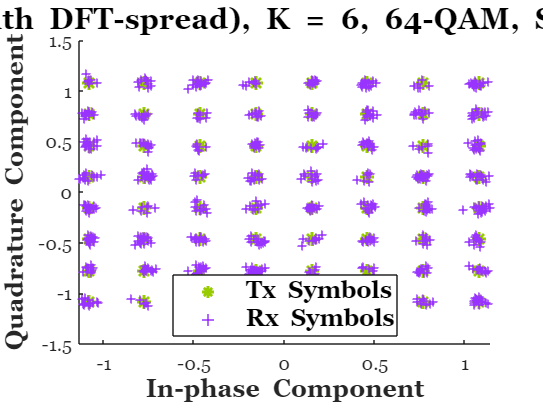

%high peak-to-average power ratio (PAPR) caused by IFFT
%minimize PAPR in UL via DFT
% PAPR: peak power is proportional to IFFT length (L)

%transmiter side
%N symbols->DFT(N)->SymbolMapper->IDFT(L=KN)->Add CP->p/S
%SymbolMapper map N symbol over the whole set of L=KN

%receiver side
%N symbols<-DFT(N)<-SymbolMapper<-IDFT(L=KN)<-remove CP<-p/S

%The DFT-S technique involves first passing the set of transmit symbols - got from a Q-ary alphabet like QAM or QPSK through a Discrete Fourier Transform (DFT) block, before they are mapped to the inputs of an Inverse Discrete Fourier Transform (IDFT) block. 
% The DFT and IDFT operations are computed very efficiently using FFT and IFFT algorithms.
%The size of the IDFT block (L) is chosen to be an integer (K) multiple of the size of the DFT block

% Boolean variable to control whether cyclic prefix is used or not:
useCP = true;

subcarrierSpacing = 312.5e3; % subcarrier spacing for 802.11a
Tu = 1/subcarrierSpacing; % the "useful" symbol period
G = 1/4; % the guard interval fraction
Tg = G*Tu; % the guard interval time
To = Tu + Tg; % the OFDM symbol duration (period)
fC = 5.5e9; % 802.11a uses the 5 GHz band
N = 52; % 48 for data, and 4 pilot tones
numPilotTones = 4; % no. pilot tones used 

K = 6; % the scale factor between the Tx-side FFT and IFFT block
L = K*N; % size of the IFFT block used on the transmitter side

% No. OFDM symbols in frame
M = 14;
%an OFDM signal with M symbols, each using N subcarriers

%QAM modulation
modOrder = 64;
bitsPerSymbol = log2(modOrder); % no. bits per complex symbol

h = [0.8; 0.51; 0.4]; % channel coefficients...

if (useCP == true)
    cpLen = G*L;
else
    cpLen = 0;
end

% Generate bit stream. 
numBits = (N)*bitsPerSymbol*M; %M symbols, each using N subcarriers
txBits = randi([0 1], numBits, 1); % the bit stream

%QAM modulation, N*bitsPerSymbol*M->N*M, 728x1
modulatedData = qammod(txBits, modOrder, "InputType", "bit", "UnitAveragePower", true);   

%Transmit frame N Tones (52)x  M (ofdm symbols)
Ftx = reshape(modulatedData, N, M); % create the transmit frame
FtxCopy = Ftx; % make a copy for Rx-side comparison

% DFT block stage:
Ftx = fft(Ftx); % compute the DFT 52x14

% Mapping type:
mapType = "interleave";
% Smybol mapper block:312x14
symbolMapOp = zeros(L, M); % the o/p of the symbol mapper
% When we map the symbols at the output of the DFT precoder
% to the inputs of the IDFT block, there will be some inputs
% left over. This will be assigned values of "0". We can work
% out the "excess" inputs as (L/2-1) - N.
% We subtract 1 from L/2 as we need to
% leave the first row of the IFFT full of 0s, this is the DC
% subcarrier.
excess = (L/2-1) - N;%102

%When interleaving mapping is used, the N output symbols
%from the DFT block are mapped over the whole set of L IDFT
%inputs, and the data symbols [c0, c1, c2,..., cN−1] are equally
%spaced out, with an appropriate number of zeros in between

switch (mapType)
    case "interleave"
        % The variable below is the amount of zeros that we will insert between
        % each symbol on the input pins of the IDFT block:
        interPadLength = floor(excess/(N-1));
        % Below we are mapping each of the (N) outputs of the DFT block to
        % the (L) inputs of the IDFT block
        for i = 1:N
            symbolMapOp(1+1+(i-1)*(interPadLength+1), :) = Ftx(i, :);
        end
    case "local"
        % insertIndex is the index where the first symbol from the output
        % of the Tx-side DFT block should be mapped to in the Tx-side IDFT
        % block. In "localised" mapping, the data (Ftx in our case) is 
        % usually padded above and below by zeros:
        insertIndex = (excess + 1)/2 + 1 + 1;
        symbolMapOp(insertIndex:insertIndex+N-1, :) = Ftx;
    otherwise
        disp("ERROR: check the value of 'mapType' at the top of the script.")
        return
end

% We need to ensure that the i/p sequence to the IDFT (IFFT) block has
% Hermitian symmetry. This will ensure that the o/p of the block is
% real-valued. In order to impose Hermitian symmetry, we must insert a
% a flipped and conjugated version of the upper half of symbolMapOp into
% its lower half. Also, the first row and the middle row must both be
% loaded with zeros (the first row is the DC subcarrier):
symbolMapOp(L/2 + 2:end, :) = conj(flip(symbolMapOp(2:L/2, :), 1));

% Pass through IFFT block:
ofdmSymbols = ifft(symbolMapOp); %LxM 312x14, complex->float

% Add the cyclic prefix: G(1/4)*L
s = [ofdmSymbols(end-cpLen+1:end, :); ofdmSymbols]; %390x14

% Pass through the channel. This involves the convolution between the
% channel - which is being modelled by a linear filter (h) - and the signal
% (s):
r = zeros(size(s, 1)+length(h)-1, M); %392x14
r_noise = zeros(size(s, 1)+length(h)-1, M);

SNRdB = 28; % channel SNR in dB

for j = 1:M % for each OFDM symbol (M=14)
    r(:, j) = conv(h, s(:, j));
    r_noise(:, j) = awgn(r(:, j), SNRdB, "measured"); % create the noisy signal
end

%Receiver side
% Remove the cyclic prefix (cpLen=78) and the tail caused by the channel delay spread.
% We should do this for each of the "M" OFDM symbols:
r_noise = r_noise(cpLen+1:end, :); %314x14
r_noise = r_noise(1:end-(length(h) - 1), :); %312x14

% Get the received frame:
Frx = fft(r_noise);%312x14 float->complex
FrxCopy = Frx; % making a copy

% Equalisation stage. First we get the channel response.
channelResponse = fft([h; zeros(L-length(h), 1)]);
% Now we perform the equalisation:
R = Frx./channelResponse; %312x14

R = R(2:L/2, :); % extracting the payload

% Rx-side Symbol Mapper:
% Now we must remove the 0s before passing the resulting sequence of
% symbols to the IDFT (IFFT) block:
switch (mapType)
    case "interleave"
        R = R(1:interPadLength+1:end, :);
    case "local"
        R = R(insertIndex+1:insertIndex+N, :);
    otherwise
        disp("ERROR: check the value of 'mappingType' at the top of the script.")
        return
end

% Pass through the Rx-side IFFT block:
R = ifft(R); %N(52)x14

R = R(:); % 728x1 turning R from a matrix to a row or column vector

% Let us define some constants that decide the colours used in the graphs:
txSymbolsColour = [0.6 0.8 0];
rxSymbolsColour1 = [0.6 0.2 1];
rxSymbolsColour2 = [0.9 0.1 0.3];

% Let us plot the constellation:
h=figure;
scatter(real(modulatedData), imag(modulatedData), 50, txSymbolsColour, 'Marker', '*', 'LineWidth', 1.5);
title("\bf\fontname{Georgia}\fontsize{12}Constellation Chart " + "(" + "DFT-spread), K = " + K + ", " + modOrder + "-" + modType + ", SNR = " + SNRdB + " dB, Equalisation at Rx");
ylabel('\bf\fontname{Georgia}\fontsize{12}Quadrature Component');
xlabel('\bf\fontname{Georgia}\fontsize{12}In-phase Component');
set(gca,'Fontname', 'Georgia');
hold on
scatter(real(R(:)), imag(R(:)), 20, rxSymbolsColour1, 'Marker', '+', 'LineWidth', 0.8);
legend({'\bf\fontname{Georgia}\fontsize{14}Tx Symbols', '\bf\fontname{Georgia}\fontsize{14}Rx Symbols'}, 'Location', 'best', 'Orientation', 'vertical');
hold off

name="dftsofdm_constellation"
saveas(h,name,'fig')
saveas(h,name,'jpg')